# Week 4 Lecture 1: Determinants, Eigenvalues, and Eigenvectors

## Determinants

We did examples of $2 \times 2$ determinants in the theory lecture.  Lets take a look at an example of a larger determinant.

Consider the matrix $A = \pmatrix{1 & 4 & -1\cr
3 & 2 & 0\cr
-1 & 4 & 3}$ we can take the determinant of this by doing.

A = [1, 4, -1; 3, 2, 0; -1, 4, 3];
det(A)

ans = -44

We can do this with another matrix $B = \pmatrix{2 & 4 & 6\cr 0 & 3 & 1\cr 0 & 0 & -5}$.

B = [2, 4, 6; 0, 3, 1; 0, 0, -5];
det(B)

ans = -30

Notice that this is just the product of the diagonal.  In any triangular matrix the determinant will be the product of its diagonal.

## Eigenvalues and Eigenvectors

Here are some more examples of eigenvalues and eigenvectors.  But in the video we will skip to the computation.

The number $\lambda$ in this equation is called an *eigenvalue* of $M$ and the vector $\mathbf{x}$ is called an *eigenvector* of $M$ corresponding to $\lambda$.  

Let's look at a few simple examples.  Let 

$M = \left(\begin{array}{c} 1 & 2 \\ 0 & 3 \end{array}\right)$ and $\mathbf{x} = \left(\begin{array}{c} 1 \\ 1 \end{array}\right)$.  

We have 

$M\mathbf{x} = \left(\begin{array}{c} 1 & 2 \\ 0 & 3 \end{array}\right) \left(\begin{array}{c} 1 \\ 1 \end{array}\right) = \left(\begin{array}{c} 3 \\ 3 \end{array}\right) = 3\mathbf{x}$.  

This means that $3$ is an eigenvalue of $M$ with corresponding eigenvector $[1,\, 1]^T$.  (Remember that the $T$ stands for transpose and just means "make this a column vector.")  

Similarly, if we keep the same matrix $M$ but let 

$\mathbf{x} = \left(\begin{array}{c} 10 \\ 10 \end{array}\right)$, 

then we have 

$M\mathbf{x} = \left(\begin{array}{c} 1 & 2 \\ 0 & 3 \end{array}\right) \left(\begin{array}{c} 10 \\ 10 \end{array}\right) = \left(\begin{array}{c} 30 \\ 30 \end{array}\right) = 3\mathbf{x}$, 

so $[10,\, 10]^T$ is also an eigenvector corresponding to the eigenvalue 3.  In fact, it is easy to check that any multiple of $[1,\, 1]^T$ is also an eigenvector with corresponding eigenvalue 3.  

However, if we instead let 

$\mathbf{x} = \left(\begin{array}{c} 0 \\ 1 \end{array}\right)$, 

then we have 

$M\mathbf{x} = \left(\begin{array}{c} 1 & 2 \\ 0 & 3 \end{array}\right) \left(\begin{array}{c} 0 \\ 1 \end{array}\right)  = \left(\begin{array}{c} 2 \\ 3 \end{array}\right)$.  

This cannot possibly be written as $\lambda\mathbf{x}$ because any multiple of $\mathbf{x}$ would have a zero in the first entry.  That means that $[0,\, 1]^T$ is *not* an eigenvector of $M$.  

It turns out (and you should experiment until you are convinced that this is true) that most vectors are not eigenvectors of $M$.  The only possible eigenvectors are multiples of $[1,\, 1]^T$ and multiples of $[1,\,0]^T$.  Moreover, there are only two eigenvalues of $M$.  We already saw that $3$ is an eigenvalue of $M$ with corresponding eigenvectors that are multiples of $[1,\,1]^T$.  It is also easy to check that $1$ is an eigenvalue of $M$ with corresponding eigenvectors that are multiples of $[1,\, 0]^T$.  Notice that $M$ was a $2\times 2$ matrix and we found 2 eigenvalues, each with a family of corresponding eigenvectors. (By "family", I mean that all the eigenvectors were multiples of each other.  The word I should really use is "subspace", but we won't go into the technical details of subspaces in this class.)  This pattern is not a coincidence.  It turns out (although we will not prove it) that *every* $n\times n$ matrix has $n$ eigenvalues, and almost every $n\times n$ matrix has $n$ different families of eigenvectors.  

There are a couple caveats about this theorem that are worth remembering.  First, the rule that there are $n$ eigenvalues of an $n\times n$ matrix works just like the rule that there are $n$ solutions to an $n$th degree polynomial, which you should already be familiar with from a basic algebra class.  In particular, it is possible for eigenvalues to be complex, and it is possible for the same eigenvalue to be repeated multiple times.  If one of the eigenvalues is complex, then its corresponding eigenvectors can also be written with complex entries.  If an eigenvalue is repeated $k$ times, then it will (almost always) have $k$ different families of eigenvectors.  It is actually possible for repeated eigenvalues to share the same family of eigenvectors (which is where the "almost" in our theorem comes from).  We won't worry about that issue in our class, because it is quite rare and makes the analysis much more complicated.  

The course videos show how to find eigenvalues and eigenvectors of a $2\times 2$ matrix by hand.  It is also possible to use that method for $3\times 3$ matrices (but it is much more difficult).  For anything larger than a $3\times 3$ matrix it is not usually possible to find eigenvalues/eigenvectors by hand.  Since we are primarily interested in large matrices, we will not worry about finding these values on paper.  Instead, we will let MATLAB do the hard work for us.  

In MATLAB, we can find the eigenvalues and eigenvectors of a matrix $M$ with the `eig` command.  This command has many different modes, and you should (as always) investigate the help file with `doc eig` to learn more about it.  We will only use two of these modes.  If you ask for only one output, such as 

M = [1 2; 0 3];
eig(M)

ans =      1
     3


then MATLAB returns a vector with all $n$ eigenvalues of $M$.  

We can also ask MATLAB for the eigenvalue decomposition or the "S, Lambda, S inverse", which gives us both the eigenvalues (saved in the diagonal of D) and the corresponding eigenvectors (saved in the respective columns of V).  Notice that MATLAB always return an eigenvector of length (distance from the origin) of unity.

[V, D] = eig(M)

V =     1.0000    0.7071
         0    0.7071


D =      1     0
     0     3


then each column of the matrix `V` will be an eigenvector of $M$ and each diagonal entry of `D` will be the corresponding eigenvalue.  (That is, `D(i, i)` is the eigenvalue corresponding to the eigenvector `V(:, i)`.)  

Lets now look at the plot from the theory lecture.

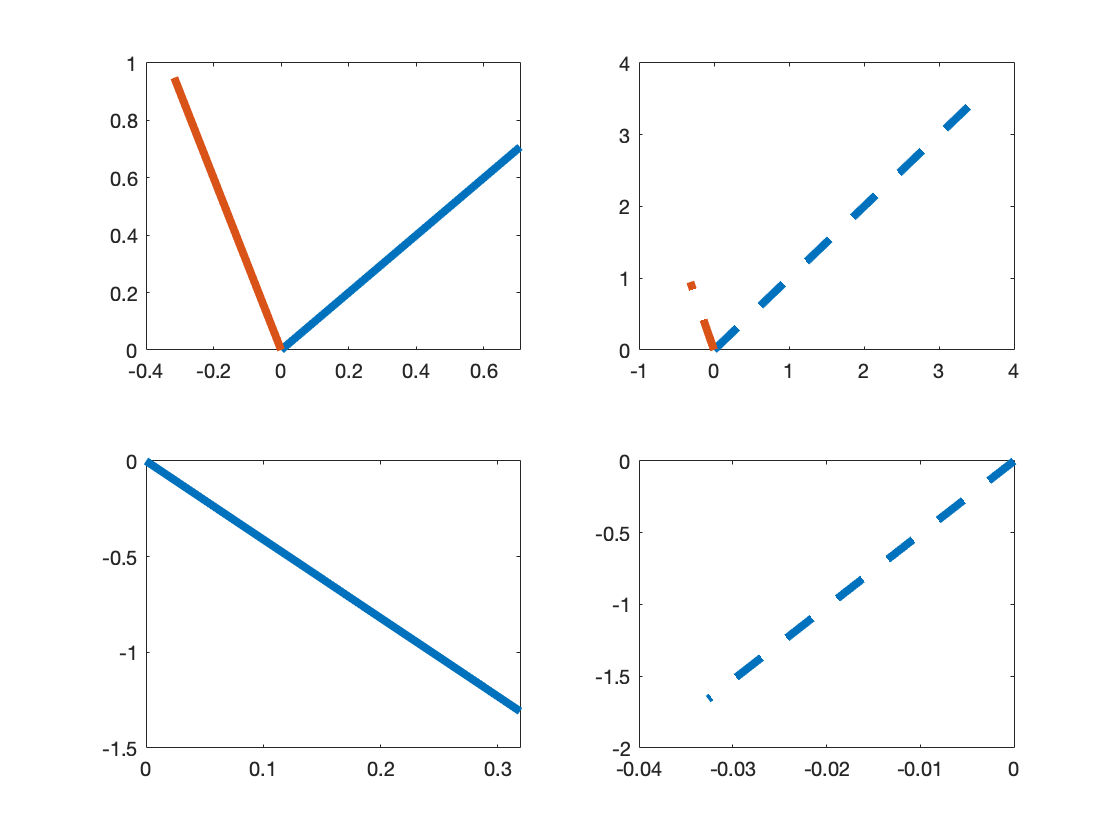

A = [4, 1; 3, 2];
[V, D] = eig(A);
v1 = V(:,1); v2 = V(:,2);
v1_x = [0:v1(1)/100:v1(1)];
v1_y = [0:v1(2)/100:v1(2)];
v2_x = [0:v2(1)/100:v2(1)];
v2_y = [0:v2(2)/100:v2(2)];
subplot(2,2,1);
plot(v1_x, v1_y, v2_x, v2_y, 'Linewidth', 4)

v1 = A*v1; v2 = A*v2;
v1_x = [0:v1(1)/100:v1(1)];
v1_y = [0:v1(2)/100:v1(2)];
v2_x = [0:v2(1)/100:v2(1)];
v2_y = [0:v2(2)/100:v2(2)];
subplot(2,2,2);
plot(v1_x, v1_y, '--', v2_x, v2_y, '--', 'Linewidth', 4)

v = randn(2,1);
v_x = [0:v(1)/100:v(1)];
v_y = [0:v(2)/100:v(2)];
subplot(2,2,3)
plot(v_x, v_y, 'Linewidth',4)

v = A*v;
v_x = [0:v(1)/100:v(1)];
v_y = [0:v(2)/100:v(2)];
subplot(2,2,4)
plot(v_x, v_y, '--', 'Linewidth',4)

#### A word on eigendecomposition

MATLAB does not just use this format because it's a convenient way to store all of the eigenvectors; the matrices $V$ and $D$ have important mathematical significance.  It turns out that we can rewrite the matrix $M$ using $V$ and $D$ as follows: 

$M = VDV^{-1}$.  

(We will verify this in MATLAB but not prove it.)  This formula is called an *eigendecomposition* of $M$.  You can check the formula in Matlab with 

[V, D] = eig(M)

V =     1.0000    0.7071
         0    0.7071


D =      1     0
     0     3


V*D*inv(V)

ans =      1     2
     0     3


It is worth noting that the eigenvectors and eigenvalues of a matrix might be complex, so there might be lots of imaginary numbers on the right side of the above equation.  We won't worry about these complex numbers for two reasons: First, they all cancel out when you multiply $VDV^{-1}$, so there won't be any complex numbers in our final answers.  Second, we will ultimately only care about the magnitude of eigenvalues, so we will only really work with real numbers.  (Remember, the magnitude of a complex number $a + bi$ is $\sqrt{a^2 + b^2}$.  You can use the MATLAB command `abs` to find the magnitude of a complex number.)  

The eigendecomposition is particularly useful for computing powers of $M$.  To see this, notice that 

$M^2 = MM = \left(VDV^{-1}\right)\left(VDV^{-1}\right) = VDV^{-1}VDV^{-1} = VDDV^{-1} = VD^2V^{-1}$, 

because the innermost $V$ and $V^{-1}$ cancel out.  (It is important to remember that you cannot reorder matrix multiplication, so we are only allowed to cancel a $V^{-1}$ and $V$ if they appear beside each other.)  

Similarly, 

$M^3 = M^2M = \left(VD^2V^{-1}\right)\left(VDV^{-1}\right) = VD^2V^{-1}VDV^{-1} = VD^2DV^{-1} = VD^3V^{-1}$.  

The pattern should quickly become apparent.  In general, we have 

$M^k = VD^kV^{-1}$.  

The reason this is so convenient is that $D$ is a diagonal matrix and it is easy to compute powers of a diagonal matrix: We just raise each entry of the matrix to the same power.  For example, 

$\left(\begin{array}{c} 2 & 0 \\ 0 & 1/3 \end{array}\right)^k = \left(\begin{array}{c} 2^k & 0 \\ 0 & (1/3)^k \end{array}\right)$.  